# Quantum Secure Direct Communication Based on Authentication

This examples implements the protocol proposed by Wang and Pan (2008) for Quantum Secure Direct Communication (QSDC) and user authentication [1].

In classical cryptography authentication ensures that communicating parties are legitimate and that no malicious entity can impersonate one of them. In this quantum protocol, authentication is achieved at the physical level using entangled states (EPR pairs) and secret keys derived from users' identities.

This protocol is composed of two phases:

- **Authentication** – Alice and Bob verify each other’s identity with the help of a trusted third party, Trent, using entangled EPR pairs and secret authentication keys.  

- **Direct communication** – once the channel is deemed secure, Alice encodes a secret message onto the remaining EPR pairs via dense coding; Bob decodes it.

Quantum Secure Direct Communication (QSDC) has evolved from the Ping-Pong scheme [2] without authentication to the first authenticated variant proposed by Lee, Lim & Yang [3], which relied on GHZ triplets. However, the GHZ approach is vulnerable if the authenticator is malicious. The protocol we are going to implement overcome this limitation by using EPR pairs: Trent masks each qubit with single-qubit Hadamard/Identity operations, allowing Alice and Bob to verify the channel and communicate securely via dense coding.

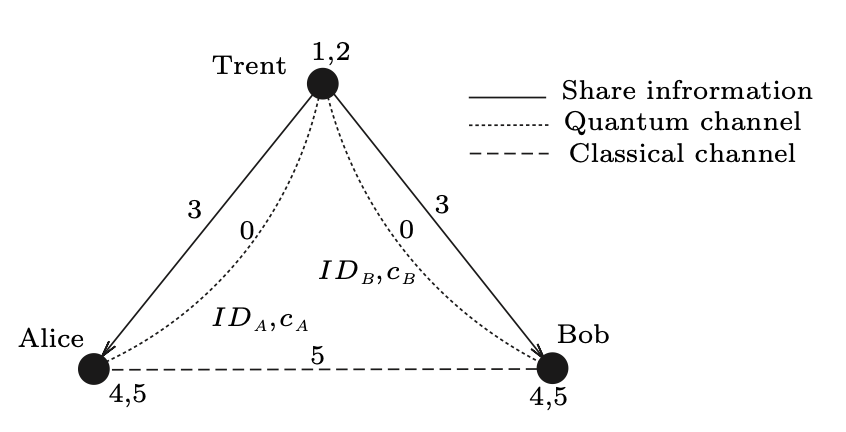

This image represents all the steps of the authentication phase and the relative communication channels, Trent has a quantum channel to both Alice and Bob to send them their qubits of each EPR pairs, Alice and Bob have a classical channel to share the result of the measurement on the check qubits

## Phase 1: Authentication

The purpose of the authentication process is to let the two legitimate communicator safely share EPR states, to ensure this each user has a secret identity sequence and a one-way hash function which are only known by the user and Trent, this information must be kept secret.

Suppose Alice identity sequence is ${\textrm{ID}}_a$ and  her one-way hash function is $h_a$, the user's authentication key shared with Trent can be calculated as $h_a \left({\;\textrm{ID}}_a \;||\;c_{a\;} \right)$ where$||\;$is a concatenation and $c_a$ is the counter of calls on the user’s hash function, $c_a$ is needed to ensure that the users authentication key is different each time.

Authentication keys are assumed to be precomputed, representing the result of a one-way hash function applied to users' identities and session counters. The detailed hash function and identity management are abstracted away for simplicity.

%% STEP 1: Initial Setup - Secret Authentication Keys Generation
% Alice and Bob each have a secret authentication key provided by Trent

% Ensure that Alice and Bob's authentication keys have the same length
Alice_key = [0 1 1 0 1];
Bob_key   = [1 0 0 1 1];

% Total number of EPR pairs generated
N = length(Alice_key);

Here are the input parameters used to share information and do the authentication check, feel free to modify them to experiment later on, but remember that to share N pairs of bits you need at least N  bits in Alice's and Bob's authentication key

%% INPUT PARAMETERS 
check_indices = [2, 5]; % indexes of the pairs used for checking
message_bits = [0 1; 1 0; 1 1]; % the message Alice is going to share with Bob
msg_indices = [1, 3, 4]; % the idexes of the qubits which contains the message to Bob

Trent generates $N$ EPR pairs in the Bell state:


$$|\Phi^+ \rangle =\frac{|00\rangle +|11\rangle }{\sqrt{2}}$$


%% STEP 2: Trent generates EPR pairs
EPRpairs = cell(1,N);
for i = 1:N
    gates = [hGate(1), cxGate(1, 2)];
    EPRpairs{i} = gates;
end

In the following image you can see the gates applied to the qubit pairs, initialized as $|00\rangle$, in order to put them in the Bell state $|\Phi^+ \rangle$

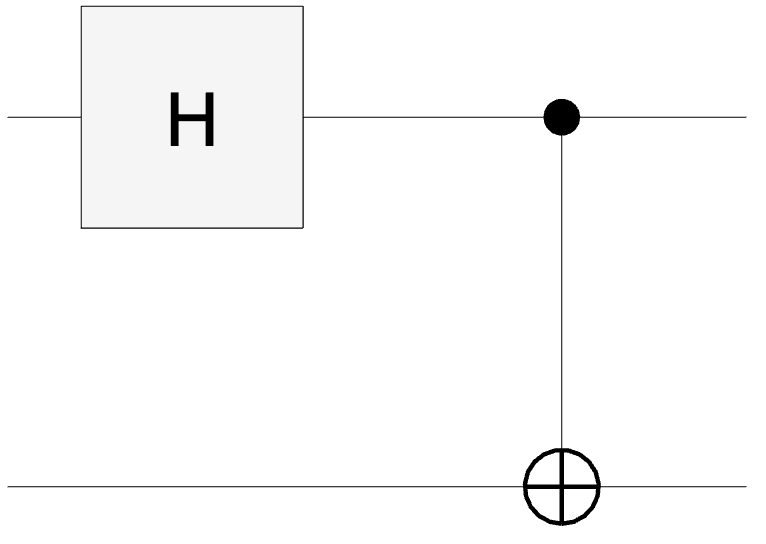 

Trent encodes each pair with a secret transformation on Alice and Bob qubits based on their secret keys.

The transformation consists in applying an Hadamard gate if the bit is 1 and an Identity gate if the bit is 0

%% STEP 3: Trent encodes the pairs using authentication keys
% Apply Hadamard gate on Alice's qubit based on Alice_key
for i = 1:N
    if Alice_key(i) == 1
        gates = EPRpairs{i};
        gates = [gates, hGate(1)];
        EPRpairs{i} = gates;
    end
    if Bob_key(i) == 1
        gates = EPRpairs{i};
        gates = [gates, hGate(2)];
        EPRpairs{i} = gates;
    end
    disp(EPRpairs{i}); % (Optional) Display the gate sequence applied so far for verification
end

  1×3 SimpleGate array with gates:

       Id   Gate   Control   Target
       1    h                1     
       2    cx     1         2     
       3    h                2     

  1×3 SimpleGate array with gates:

       Id   Gate   Control   Target
       1    h                1     
       2    cx     1         2     
       3    h                1     

  1×3 SimpleGate array with gates:

       Id   Gate   Control   Target
       1    h                1     
       2    cx     1         2     
       3    h                1     

  1×

Trent now sends the first qubit of each EPR pair to Alice and the second qubit to Bob, using a quantum channel.

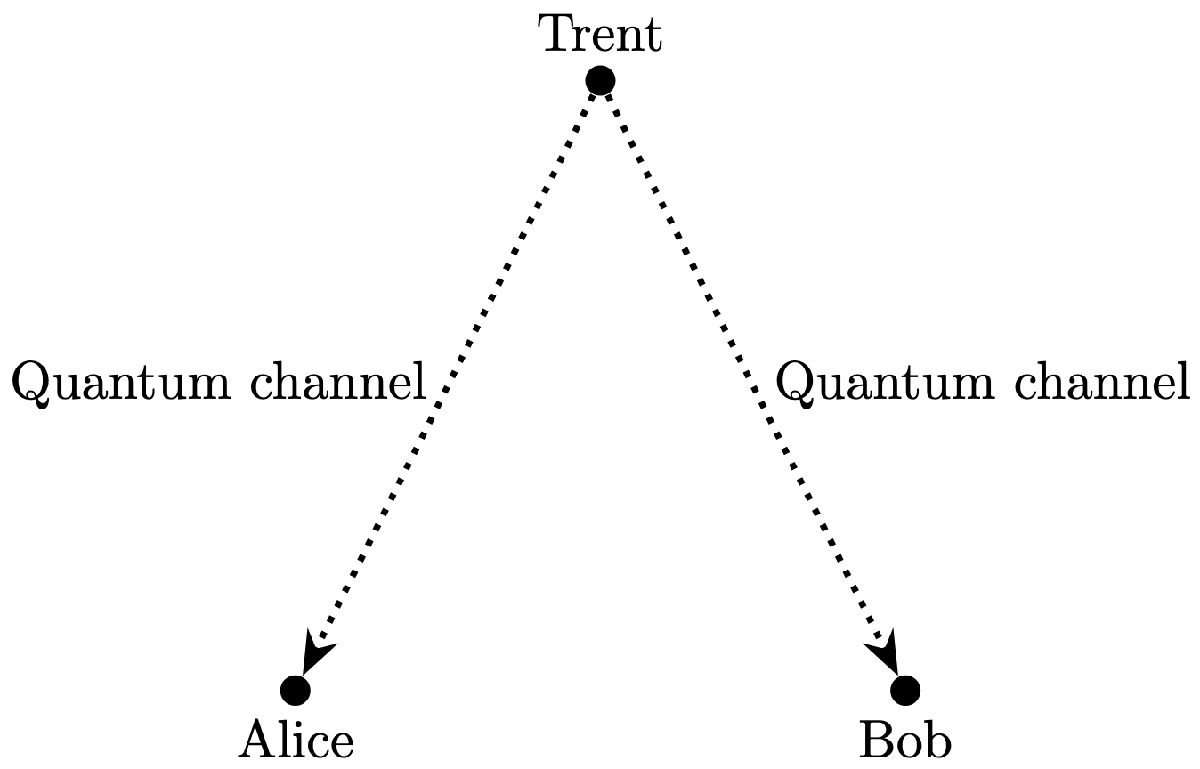

At this point Alice and Bob must check whether someone has interfered with their communication with Trent, to do so they apply the same secret transformation based on their authentication key, given the fact that both Hadamard gates and Identity gates are self-inverse operations ($H_{\textrm{gate}}^2 =I_{\textrm{gate}} \;\;\textrm{and}\;\;I_{\textrm{gate}}^2 =I_{\textrm{gate}}$), if everything worked out, they should mesure the original state $|\Phi^+ \rangle =\frac{|00\rangle +|11\rangle }{\sqrt{2}}$

%% STEP 4: Alice and Bob decode the pairs using their respective keys
for i = 1:N
    if Alice_key(i) == 1
        gates = EPRpairs{i};
        gates = [gates, hGate(1)];
        EPRpairs{i} = gates;
    end
    if Bob_key(i) == 1
        gates = EPRpairs{i};
        gates = [gates, hGate(2)];
        EPRpairs{i} = gates;
    end
end

After decoding, Alice and Bob select some pairs (check set), measure them and compare the results with each other through a classical channel

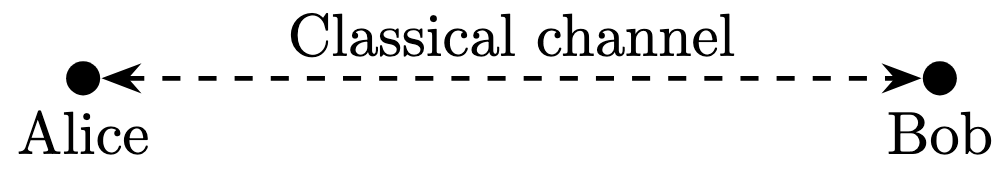

 if they always get a coherent result ($|00\rangle$ or $|11\rangle$) there were no interference and the authentication succeeded, if they see some differences someone intercepted and alterated the qubits and the communication is interrupted.

as you can see, unlike the earlier “Ping-Pong” protocol by Boström & Felbinger [2], this scheme includes an explicit authentication layer, any man-in-the-middle attack that might succeed against Ping-Pong is detected here by comparing Alice's and Bob's pairs.

%% STEP 5: Authentication check (eavesdropping control)
% to change this modify check_indices at the beginning of the script

% If interception occurs, the state probabilities will change
for idx = check_indices
    result = simulate(quantumCircuit(EPRpairs{idx}, 2));
    [states, P] = querystates(result);
    fprintf(" ");
    fprintf("qubit: %i measurement probabilities", idx);
    fprintf(" ");
    T = table(states,P);
    T = sortrows(T,"P","descend")
end

qubit: 2 measurement probabilities

T = 2×2 table
    states     P 
    ______    ___

     "00"     0.5
     "11"     0.5


qubit: 5 measurement probabilities

T = 2×2 table
    states     P 
    ______    ___

     "00"     0.5
     "11"     0.5


## Phase 2: **Direct communication**

Now Alice can prepare her secret message appying transformations on her qubits and send them to Bob, Alice encodes her message using the two-step dense-coding scheme of Deng, Long & Liu [4]: 00 → I, 01 → Z, 10 → X, 11 → Y. 

This doubles the classical capacity:  1 qubit ↔ 2 classical bits

%% STEP 6: Alice encodes a secret message using Dense Coding
% to change this modify message_bits at the beginning of the script
% Message → quantum gate correspondence:
% 00 → Identity, 01 → Z gate, 10 → X gate, 11 → Y gate
coding_gates = {@idGate, @zGate, @xGate, @yGate};

% Alice applies the operation corresponding to the message bits
for k = 1:size(message_bits,1)
    b0 = message_bits(k,1);
    b1 = message_bits(k,2);
    idx = 2 * b1 + b0 + 1;
    gates = EPRpairs{msg_indices(k)};
    gates = [gates, coding_gates{idx}(1)];
    EPRpairs{msg_indices(k)} = gates;
end

%% STEP 7: Alice sends the quantum message to Bob
% This step is implicitly simulated by variable passing in MATLAB

Alice sends her qubits to Bob

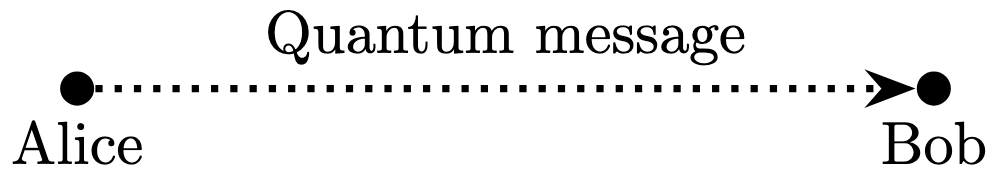

Finally Bob decodes the qubits to read Alice's messaage

%% STEP 8: Bob decodes and measures the received message (Bell basis decoding)
% Apply decoding circuit to transform Bell states into computational basis
for k = 1:size(message_bits,1)
    % Add Bell basis decoding gates
    gates = EPRpairs{msg_indices(k)};
    gates = [gates, cxGate(1, 2)];
    gates = [gates, hGate(1)];
    EPRpairs{msg_indices(k)} = gates;

    % Simulate and extract measurement results
    result = simulate(quantumCircuit(EPRpairs{msg_indices(k)}));
    [states, P] = querystates(result);
    disp(['Message measurement result for pair ', num2str(msg_indices(k))]);
    T = table(states, P);
    T = sortrows(T,"P","descend")

    % Determine the most probable Bell state and decode it
    [~, max_idx] = max(P);
    measured_state = states(max_idx);

    % Decode based on Bell basis outcome
    switch measured_state
        case "00"
            decoded = [0 0]; % Φ+
        case "01"
            decoded = [0 1]; % Φ−
        case "10"
            decoded = [1 0]; % Ψ+
        case "11"
            decoded = [1 1]; % Ψ−
        otherwise
            decoded = [NaN NaN];
    end
    disp(['Decoded bits for pair ', num2str(msg_indices(k)), ': ', num2str(decoded)]);
    fprintf(" ");
end

Message measurement result for pair 1


T = 1×2 table
    states    P
    ______    _

     "01"     1


Decoded bits for pair 1: 0  1


Message measurement result for pair 3


T = 1×2 table
    states    P
    ______    _

     "10"     1


Decoded bits for pair 3: 1  0


Message measurement result for pair 4


T = 1×2 table
    states    P
    ______    _

     "11"     1


Decoded bits for pair 4: 1  1


As you can see the qubits Bob measures with the Bell basis correspons to the ones Alice wantend to send, with probability 1.

## References

[1] Wang Min-Jie and Pan Wei 2008. Quantum Secure Direct Communication Based on Authentication

[2] Kim Boström and Timo Felbinger. Deterministic Secure Direct Communication Using Entanglement

[3] Min-Jie, W., & Wei, P. (2008). Quantum secure direct communication based on authentication

[4] Fu-Guo Deng, Gui Lu Long and Xiao-Shu Liu. Two-step quantum direct communication protocol using the Einstein-Podolsky-Rosen pair block